# Deflection Analysis of Bracket

This example shows how to analyze an idealized 3-D mechanical part under an applied load using Finite Element Analysis (FEA). The objective of the analysis is to determine the maximal deflection caused by the load.

## Create a Structural Analysis Model

The first step in solving a linear elasticity problem is to create a structural analysis model. This is a container that holds the geometry, structural material properties, body and boundary loads, boundary constraints, and mesh.

model = createpde('structural','static-solid');

## Import the Geometry

Import an STL file of a simple bracket model using the `importGeometry` function. This function reconstructs the faces, edges and vertices of the model. It can merge some faces and edges, so the numbers can differ from those of the parent CAD model.

importGeometry(model,'BracketWithHole.stl');

Plot the geometry and turn on face labels. You will need the face labels to define the boundary conditions.

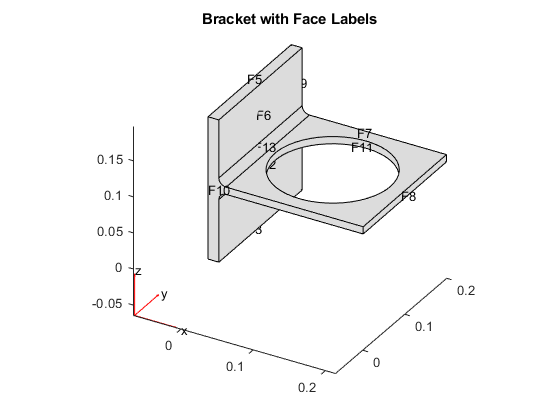

figure
pdegplot(model,'FaceLabels','on')
view(30,30);
title('Bracket with Face Labels')

## Specify Structural Properties of the Material

Specify Young's modulus and Poisson's ratio for this material.

structuralProperties(model,'Cell',1,'YoungsModulus',200e9, ...
                                    'PoissonsRatio',0.3);

## Define the Boundary Conditions

The problem has two boundary conditions: the back face (face 4) is immobile and the front face has an applied load. All other boundary conditions, by default, are free boundaries.

structuralBC(model,'Face',4,'Constraint','fixed');

Apply a distributed load in the negative $z$-direction to the front face (face 8).

distributedLoad = 1e4; % Applied load in Pascals
structuralBoundaryLoad (model,'Face',8,'SurfaceTraction',[0;0;-distributedLoad]);

## Create a Mesh

Create a mesh that uses 10-node tetrahedral elements with quadratic interpolation functions. This element type is significantly more accurate than the linear interpolation (four-node) elements, particularly in elasticity analyses that involve bending.

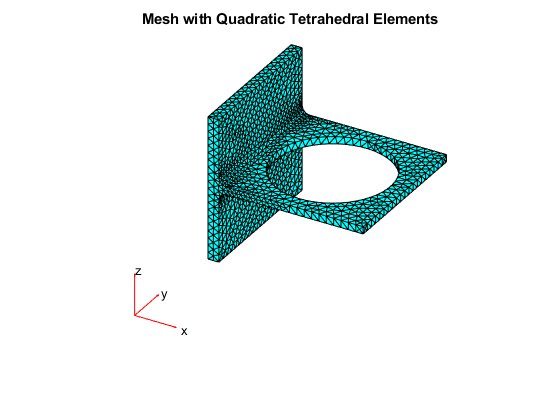

bracketThickness = 1e-2; % Thickness of horizontal plate with hole, meters
%generateMesh(model,'Hmax',bracketThickness);
figure
pdeplot3D(model)
title('Mesh with Quadratic Tetrahedral Elements');

## Calculate the Solution

Use `solve` to calculate the solution.

result = solve(model);

## Examine the Solution

Find the maximal deflection of the bracket in the $z$ direction.

minUz = min(result.Displacement.uz);
fprintf('Maximal deflection in the z-direction is %g meters.', minUz)

Maximal deflection in the z-direction is -4.48952e-05 meters.

## Plot Components of the Displacement

To see the solution, plot the components of the solution vector. The maximal deflections are in the $z$-direction. Because the part and the loading are symmetric, the $x$-displacement and $z$-displacement are symmetric, and the $y$-displacement is antisymmetric with respect to the center line.

Here, the plotting routine uses the `'jet'` colormap, which has blue as the color representing the lowest value and red representing the highest value. The bracket loading causes face 8 to dip down, so the maximum $z$-displacement appears blue.

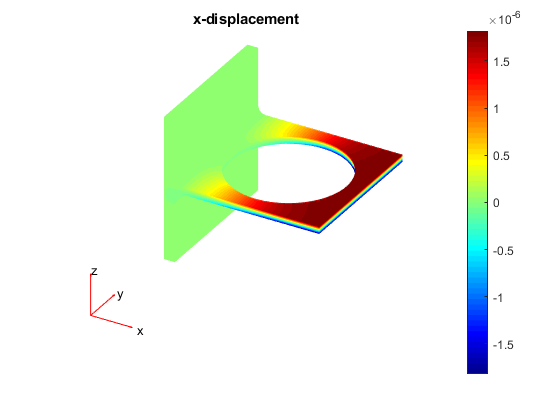

pdeplot3D(model,'ColorMapData',result.Displacement.ux)
title('x-displacement')
colormap('jet')

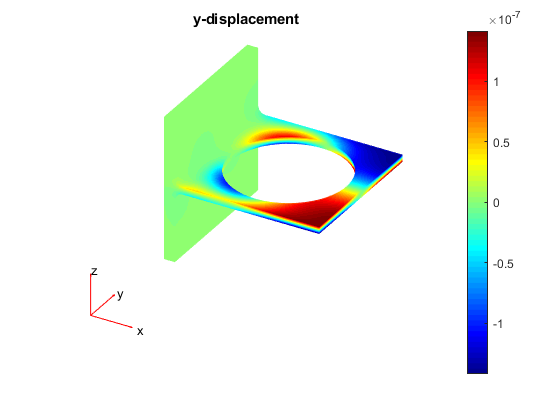

pdeplot3D(model,'ColorMapData',result.Displacement.uy)
title('y-displacement')

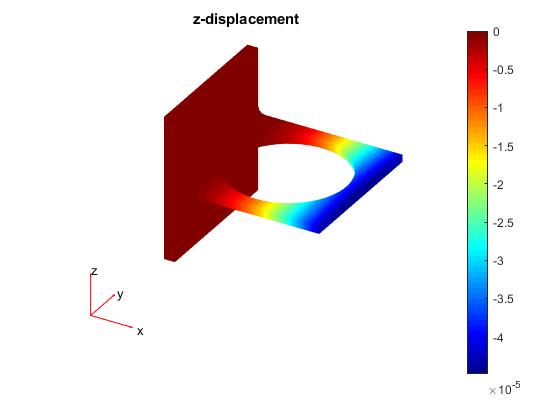

pdeplot3D(model,'ColorMapData',result.Displacement.uz)
title('z-displacement')

## Plot von Mises Stress

Plot values of the von Mises Stress at nodal locations. Use the same `jet` colormap.

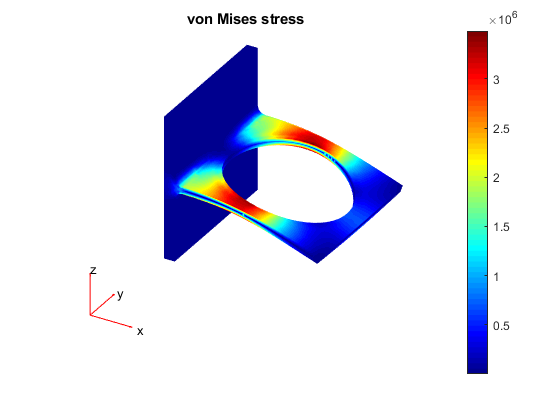

figure
pdeplot3D(model,'ColorMapData',result.VonMisesStress,'Deformation',result.Displacement,'DeformationScaleFactor',1000)
title('von Mises stress')

*Copyright 2014-2018 The MathWorks, Inc.*